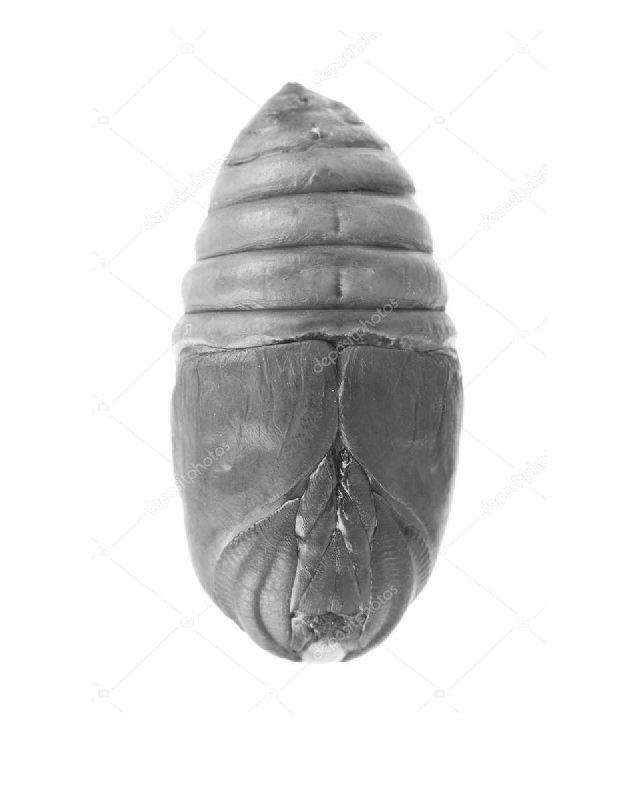

test=rgb2gray(imread('betterer.jpg')); 
imshow(test)

size(test)

ans =         1023         682


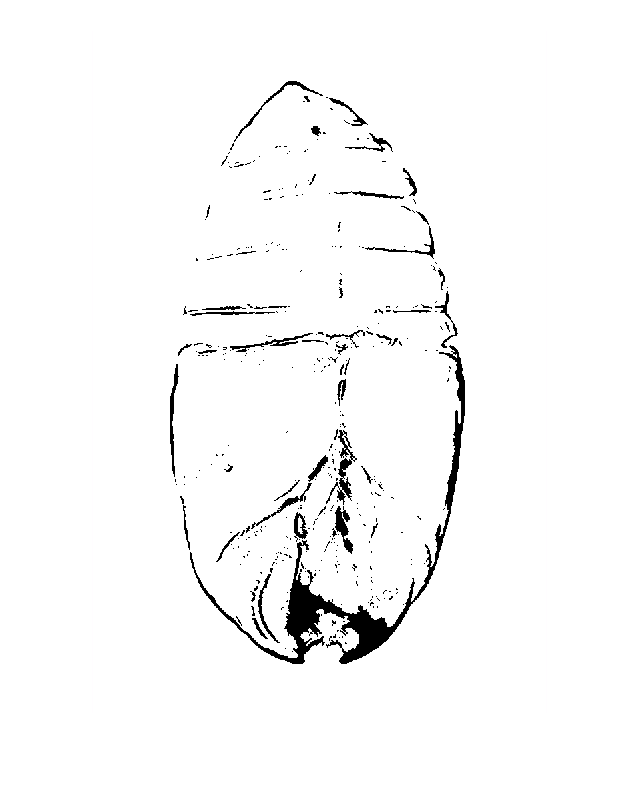

W= gradientweight(test, 4, 'RolloffFactor', 4, 'WeightCutoff', .3);
mask=false(size(test));
mask(1,1)=true;
segtest=imsegfmm(W,mask,0.24);
imclearborder(segtest);
imshow(segtest)

W1= gradientweight(test, 3, 'RolloffFactor', 4, 'WeightCutoff', .22);
mask1=false(size(test));
mask1(1,1)=true;
segtest1=imsegfmm(W1,mask1,0.24);
imclearborder(segtest1);
imshow(segtest1)